# Create Table Entries That Span Multiple Columns

Use the `ColSpan` property to specify that a table entry spans multiple columns. 

Create a presentation.

import mlreportgen.ppt.*
ppt = Presentation("myColSpan.pptx");
open(ppt);

Add a slide to the presentation.

slide = add(ppt,"Title and Table");

Create a table that has four columns.

t = Table(4);
t.StyleName = "Medium Style 2 - Accent 1";
t.Style = {VAlign("middleCentered")};

Create the header row. This row has a single table entry that spans all four columns.

tr1 = TableRow();
tr1te1 = TableEntry("Header Row");
tr1te1.ColSpan = 4;
append(tr1,tr1te1);
append(t,tr1);

Create the subheader row. This row has two table entries, each of which spans two columns.

tr2 = TableRow();
tr2te1 = TableEntry("Subheader 1");
tr2te1.ColSpan = 2;
append(tr2,tr2te1);
tr2te2 = TableEntry("Subheader 2");
tr2te2.ColSpan = 2;
append(tr2,tr2te2);
append(t,tr2);

Create the content row. This row has four table entries each of which spans a single column.

tr3 = TableRow();
append(tr3,TableEntry("entry(1,1)"));
append(tr3,TableEntry("entry(1,2)"));
append(tr3,TableEntry("entry(1,3)"));
append(tr3,TableEntry("entry(1,4)"));
append(t,tr3);

Add a title and the table to the slide.

replace(slide,"Title","Table Entry That Spans Multiple Columns");
replace(slide,"Table",t);

Close and view the presentation.

close(ppt);
rptview(ppt);

Here is the slide in the generated presentation:

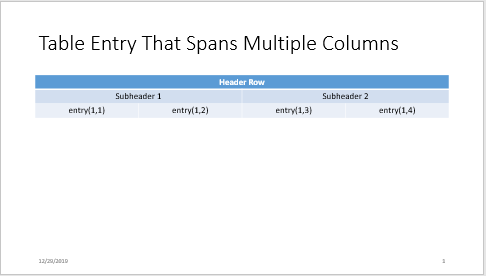

*Copyright 2019 The MathWorks, Inc.*